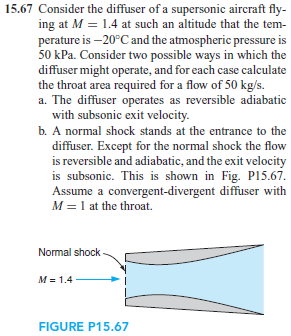

# classes

u = symunit;
air = ig;

# part A

## inflow properties

pi = 50*u.kPa;
Ti = -20*u.Celsius;
rhoi = rewrite(pi/(air.R*c2k(Ti)), 'SI');
rhoi_vpa = vpa(rhoi, 4)

$$rhoi\_vpa = 0.6882\,\frac{\mathrm{kg}}{m^{3}}$$

Mi = 1.4;
Vi = Mi*simplify(sqrt(air.gamma*air.R*c2k(Ti)));
Vi_vpa = vpa(Vi, 5)

$$Vi\_vpa = 446.5\,\frac{m}{s}$$

mdoti = 50*u.kg/u.s;
Ai = mdoti/(rhoi*Vi);
Ai_vpa = vpa(Ai, 4)

$$Ai\_vpa = 0.1627\,m^{2}$$

## cross sectional area of the throat

syms As;
As = solve(Ai/As == air.A_As(Mi));
As_vpa = vpa(As, 4)

$$As\_vpa = 0.1459\,m^{2}$$

# part B

## upstream shock properties

px = 50*u.kPa;
Tx = -20*u.Celsius;
Mx = 1.4;
pox = px/air.p_po(Mx);
pox_vpa = vpa(pox, 5)

$$pox\_vpa = 159.11\,\mathrm{kPa}$$

Tox = c2k(Tx)/air.T_To(Mx);
Tox_vpa = vpa(Tox, 5)

$$Tox\_vpa = 352.38\,K$$

Ax = Ai;

## downstream shock properties

My = air.My(Mx);
My_vpa = vpa(My, 4)

$$My\_vpa = 0.7397$$

poy_pox = air.poy_pox(Mx);
poy = pox*poy_pox;
poy_vpa = vpa(poy, 5)

$$poy\_vpa = 152.46\,\mathrm{kPa}$$

Toy = Tox;

## cross sectional area of the throat

syms Ays;
Ax_As = air.A_As(Mx);
Ays = solve(Ax/Ays == Ax_As*poy_pox);
Ays_vpa = vpa(Ays, 4)

$$Ays\_vpa = 0.1523\,m^{2}$$